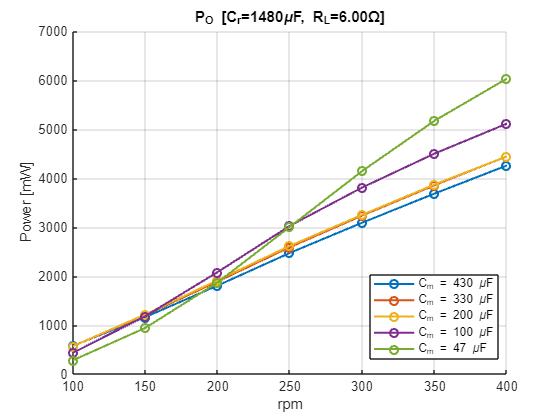


% Dati misurati con i tre bridge NVC gia' collegati in parallelo (NVC_1+2+3_f_sweep.csv):
% sweep di rpm per 5 valori fissi del condensatore di compensazione C_m, R_L = 6 Ohm
% fisso (valore reale di questa misura in parallelo, diverso dai carichi dei bridge singoli
% usati nel calcolo per bridge separato di C_sweep.mlx/R_sweep.mlx).
% CORREZIONI (valori anomali di un ordine di grandezza rispetto alle celle vicine della
% stessa riga/colonna, stesso tipo di errore di virgola gia' visto negli altri file):
%   rpm=100, C_m=200uF : Po  56.887  -> 568.87
%   rpm=150, C_m=47uF  : Pi 166.068  -> 1660.68
%   rpm=200, C_m=330uF : Pi 295.1    -> 2951.0
%   rpm=250, C_m=47uF  : Pi 487.07   -> 4870.7
%   rpm=300, C_m=430uF : Po 308.963  -> 3089.63
%   rpm=300, C_m=200uF : Pi 481.765  -> 4817.65
%   rpm=350, C_m=430uF : Po 368.306  -> 3683.06 , Pi 532.056 -> 5320.56
%   rpm=350, C_m=200uF : Pi 563.969  -> 5639.69
%   rpm=400, C_m=200uF : Pi 639.554  -> 6395.54

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 6;            % Ohm - carico fisso durante la misura in parallelo

rpm_plot = [100 150 200 250 300 350 400];
C_L_plot = [430 330 200 100 47]*1e-6;   % F
n_CL = numel(C_L_plot);
colors = lines(n_CL);

% Potenza totale misurata con i tre bridge in parallelo, colonne = C_L_plot, righe = rpm_plot
P_real_tot_mW = [ ...
     577.051  568.574  568.870  433.322  280.937; ...
    1161.486 1201.984 1216.074 1181.846  940.781; ...
    1806.061 1889.706 1914.886 2081.096 1870.064; ...
    2472.505 2589.969 2616.579 3026.508 3005.614; ...
    3089.630 3234.652 3250.549 3807.637 4144.403; ...
    3683.060 3853.597 3868.507 4499.171 5170.465; ...
    4256.729 4442.665 4443.649 5110.765 6030.358];
P_real_tot = P_real_tot_mW/1000;

% Potenza in ingresso misurata (stessa disposizione), usata per l'efficienza sotto
P_in_tot_mW = [ ...
    1015.897 1017.819 1022.037  832.533  609.633; ...
    1876.022 1967.897 1993.338 2004.074 1660.680; ...
    2787.135 2951.000 2994.558 3364.592 3131.519; ...
    3705.191 3921.139 3966.523 4720.855 4870.700; ...
    4530.076 4786.681 4817.650 5788.334 6519.585; ...
    5320.560 5613.207 5639.690 6709.435 7930.267; ...
    6074.506 6387.661 6395.540 7518.051 9091.755];

% Rendimento di raddrizzamento eta_rec = P_O/P_I, calcolato dai dati reali sopra
eta_in = P_real_tot_mW ./ P_in_tot_mW;

% PEE (Power Extraction Efficiency = P_real/P_matched) omessa per ora:
% manca il riferimento di potenza a carico adattato P_matched(rpm).


figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_tot(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('Power [mW]');

legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

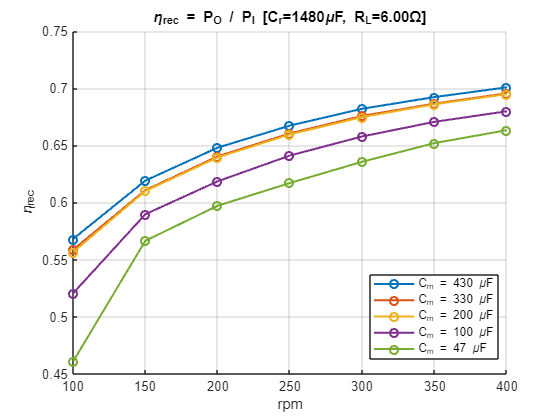



%{
%%%PEE
figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, Pee(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('PEE = P_{Real} / P_{Matched} [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('PEE');

legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;
%}


%%%efficiency
figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, eta_in(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('\\eta_{rec} = P_{O} / P_{I} [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('\eta_{rec}');

legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;